# **Sesión 2. Sucesiones y límites**

# 2.1. Cálculo de límites

Matlab tiene implementada la función limit para calcular el límite (en caso de exisitir) de sucesiones $a_n$ cuando $n$ tiende a infinito.

help limit

--- help for sym/limit ---

 limit    Limit of an expression.
    limit(F,x,a) takes the limit of the symbolic expression F as x -> a.
    limit(F,a) uses symvar(F) as the independent variable.
    limit(F) uses a = 0 as the limit point.
    limit(F,x,a,'right') or limit(F,x,a,'left') specify the direction
    of a one-sided limit.
 
    Examples:
      syms x a t h;
 
      limit(sin(x)/x)                 returns   1
      limit((x-2)/(x^2-4),2)          returns   1/4
      limit((1+2*t/x)^(3*x),x,inf)    returns   exp(6*t)
      limit(1/x,x,0,'right')          returns   inf
      limit(1/x,x,0,'left')           returns   -inf
      limit((sin(x+h)-sin(x))/h,h,0)  returns   cos(x)
      v = [(1 + a/x)^x, exp(-x)];
      limit(v,x,inf,'left')           returns   [exp(a),  0]

    Documentation for sym/limit



Previamente, deberemos declarar la variable $n$ como simbólica:

syms n

Y a continuación calcular el límite con

`limit(sucesión, n, inf)`

**Ejemplo: **Calculemos el límite de la siguiente sucesión:


$$a_n= 16\cdot 2^{-n}.$$


syms n
an=16*2^(-n)

$$an = \frac{16}{2^{n}}$$

limit(an,n,inf)

$$ans = 0$$

Podemos observar que la sucesión converge al valor 0.

# 2.2. Límites con indeterminaciones

#### Indeterminación $\frac{\infty}{\infty}$

Recordemos que cuando tenemos una sucesión representada por un cociente de polinomios:

- Si el grado del numerador es mayor que el del denominador, el resultado del límite será infinito.

- Si el grado del numerador es igual al del denominador, el resultado del límite será el cociente de los coeficientes de la variable de mayor potencia.

- Si el grado del numerador es menor que el del denominador, el resultado del límite será cero.

**Ejercicio 1. **Calcula los siguientes límites:

a) $\lim_{n\to \infty } \frac{\;2n^3 +5n^2 -4}{n-5}$

limit((2*n^3+5*n^2-4)/(n-5),inf)

$$ans = \infty$$

b) $\lim_{n\to \infty } \frac{n^3 -n^2 -1}{3n^3 +7}$

limit((n^3-n^2-1)/(3*n^3+7),inf)

$$ans = \frac{1}{3}$$

c) $\lim_{n\to \infty } \frac{n^3 +5n^2 -4}{n^5 +n-2}$

limit((n^3+5*n^2-4)/(n^5+n-2),inf)

$$ans = 0$$

#### Indeterminación $1^{\infty}$

**Ejercicio 2. **Calcula los siguientes límites:

a) $\lim_{n\to \infty } {\left(\frac{2n^2 +5n-4}{2n^2 -5}\right)}^{n+1}$

limit(((2*n^2+5*n-4)/(2*n^2-5))^(n+1),inf)

$$ans = {\mathrm{e}}^{5/2}$$

b) $\lim_{n\to \infty } {\left(1-\frac{n^3 -n^2 -1}{n^4 +7}\right)}^n$

limit((1-(n^3-n^2-1)/(n^4+7))^n,inf)

$$ans = {\mathrm{e}}^{-1}$$

c) $\lim_{n\to \infty } {\left({\left(\frac{2n+3}{4}\right)}^4 \;\frac{256}{16\;n^4 +7}\right)}^{2n}$

limit((((2*n+3)/4)^(4))*(256/(16*n^4+7))^(2*n),inf)

$$ans = 0$$

# 2.3. Representación del concepto de límite

Recuerda que para realizar una partición equidistante de puntos en un intervalo, utilizamos la notación de dos puntos:

**primer elemento : salto : último elemento**

**Ejemplo: **subdivide en $n=10$ partes (10 subintervalos, o equivalentemente, 11 puntos) el intervalo $[a,b]=[1,2]$:

El salto vendrá dado por $h=\frac{b-a}{n}=\frac{2-1}{10}=0.1$

1:0.1:2

ans =        1             11/10           6/5           13/10           7/5            3/2            8/5           17/10           9/5           19/10           2       


Observa que también podemos hacer lo mismo utilizando la función `linspace` de matlab:

linspace(1,2,11)

ans =        1             11/10           6/5           13/10           7/5            3/2            8/5           17/10           9/5           19/10           2       


# Comando plot

Para dibujar en Matlab una sucesión en el intervalo $[a,b]$ hacemos en primer lugar una partición del intervalo que vendrá recogida en el vector $x$; seguidamente definimos la función en el vector $y$, y por último, hacemos actuar la orden `plot.`

help plot

 plot   Linear plot. 
    plot(X,Y) plots vector Y versus vector X. If X or Y is a matrix,
    then the vector is plotted versus the rows or columns of the matrix,
    whichever line up.  If X is a scalar and Y is a vector, disconnected
    line objects are created and plotted as discrete points vertically at
    X.
 
    plot(Y) plots the columns of Y versus their index.
    If Y is complex, plot(Y) is equivalent to plot(real(Y),imag(Y)).
    In all other uses of plot, the imaginary part is ignored.
 
    Various line types, plot symbols and colors may be obtained with
    plot(X,Y,S) where S is a character string made from one element
    from any or all the following 3 columns:
 
           b     blue          .     point              -     solid
           g     green         o     circle             :     dotted
           r     red           x     x-mark         

**Ejemplo. **Representar la sucesión de término general $a_n =3^{-n}$ en el intervalo [1,10]

*1. Definimos una partición de [1,10] en subintervalos de longitud 1/10:*

n=1:0.1:10

n =        1             11/10           6/5           13/10           7/5            3/2            8/5           17/10           9/5           19/10           2             21/10          11/5           23/10          12/5            5/2           13/5           27/10          14/5           29/10           3             31/10          16/5           33/10          17/5            7/2           18/5           37/10          19/5           39/10           4             41/10          21/5           43/10          22/5            9/2           23/5           47/10          24/5           49/10           5             51/10          26/5           53/10          27/5           11/2           28/5           57/10          29/5           59/10           6             61/10          31/5           63/10          32/5           13/2           33/5           67/10          34/5           69/10           7             71/10          36/5           73/10          37/5           15/2           

*2. Evaluamos todos los puntos de la partición en el término de la sucesión:*

y=3.^(-n)

y =        1/3          399/1336       449/1678       111/463        569/2649       260/1351       439/2546       389/2518       227/1640       943/7604         1/9          133/1336       501/5617        37/463        599/8366       260/4053       148/2575       389/7554       181/3923       351/8491         1/27         133/4008       167/5617        37/1389       589/24679      179/8371        97/5063       389/22662      136/8843       117/8491         1/81         101/9131        94/9485        37/4167       193/24260      206/28901      114/17851      118/20623      136/26529       39/8491         1/243         78/21155       87/26336       59/19934       61/23003      206/86703       38/17851       51/26740      141/82513       13/8491         1/729         26/21155       29/26336       32/32435       44/49777      206/260109      38/53553       17/26740       47/82513       13/25473        1/2187        26/63465       17/46315       32/97305        9/30545      205/776539      

**Nota: **es muy importante que precedas las operaciones de producto, división y potencia de un punto (.) para que se realicen **elemento a elemento** y el resultado sea un vector de la misma dimensión.

*3. Representamos los términos de la sucesión con plot:*

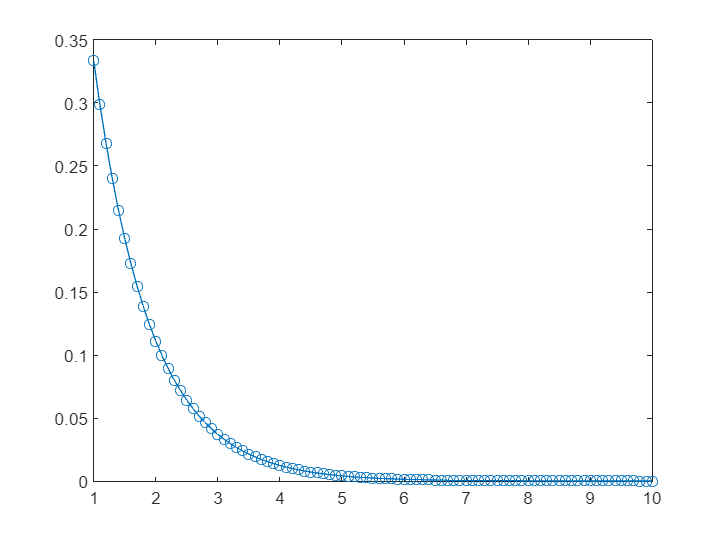

plot(n,y,'o-')

*4. Según la gráfica, ¿Qué podemos decir de su convergencia?. Compruebalo con la función limit(a_n,n).*

En la gráfica podemos ver que la sucesión converge al valor 0. Lo comprobamos en Matlab:

syms x
limit(3^(-x),x,inf)

$$ans = 0$$

**Ejercicio 3. **Representar las sucesiones de término general $a_n =e^{-n}$ y $b_n =e^n$ tomando 100 puntos en el intervalo [1,10].

n = linspace(1,10,100)

n =        1             12/11          13/11          14/11          15/11          16/11          17/11          18/11          19/11          20/11          21/11           2             23/11          24/11          25/11          26/11          27/11          28/11          29/11          30/11          31/11          32/11           3             34/11          35/11          36/11          37/11          38/11          39/11          40/11          41/11          42/11          43/11           4             45/11          46/11          47/11          48/11          49/11          50/11          51/11          52/11          53/11          54/11           5             56/11          57/11          58/11          59/11          60/11          61/11          62/11          63/11          64/11          65/11           6             67/11          68/11          69/11          70/11          71/11          72/11          73/11          74/11          75/11          76/11          

a = exp(-n)

a =      536/1457       391/1164       607/1979       503/1796       491/1920       315/1349       384/1801       491/2522       427/2402       249/1534       328/2213       329/2431       401/3245       516/4573      1251/12142      386/4103       209/2433       255/3251       239/3337        79/1208       138/2311       147/2696       152/3053       341/7501       232/5589       107/2823       236/6819       205/6487       119/4124       280/10627      122/5071       117/5326        41/2044       107/5842       277/16563       33/2161        53/3801        83/6519       176/15139      123/11587       89/9182        77/8700        50/6187        31/4201        46/6827        80/13003      162/28837      113/22029        2/427        237/55415      155/39691       34/9535        23/7064        25/8409        35/12893        7/2824        96/42415       31/15000       38/20137       17/9866        53/33686       41/28539       22/16771       15/12523       28/25601      104/104139      

b = exp(n)

b =     1457/536       1164/391       1979/607       1796/503       1920/491       1349/315       1801/384       2522/491       2402/427       1534/249       2213/328       2431/329       3245/401       4573/516      12142/1251      4103/386       2433/209       3251/255       3337/239       1208/79        2311/138       2696/147       3053/152       7501/341       5589/232       2823/107       6819/236       6487/205       4124/119      10627/280       5071/122       5326/117       2044/41        5842/107      16563/277       2161/33        3801/53        6519/83       15139/176      11587/123       9182/89        8700/77        6187/50        4201/31        6827/46       13003/80       28837/162      22029/113        427/2        55415/237      39691/155       9535/34        7064/23        8409/25       12893/35        2824/7        42415/96       15000/31       20137/38        9866/17       33686/53       28539/41       16771/22       12523/15       25601/28      104139/104      328

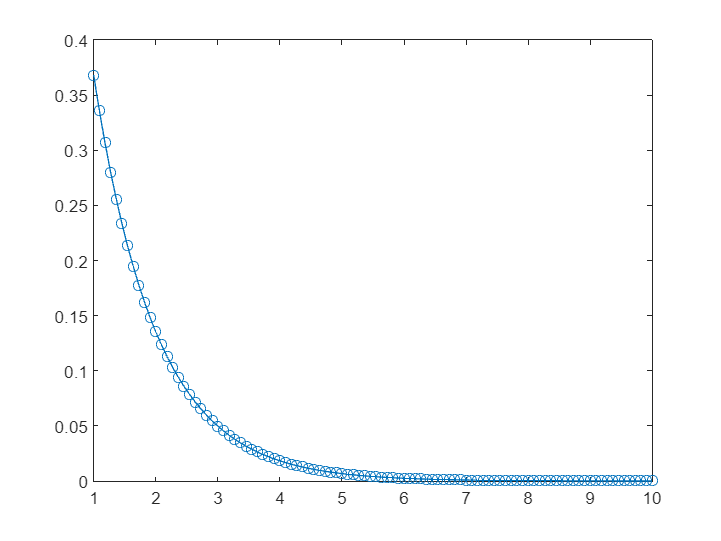

plot(n,a,'o-')

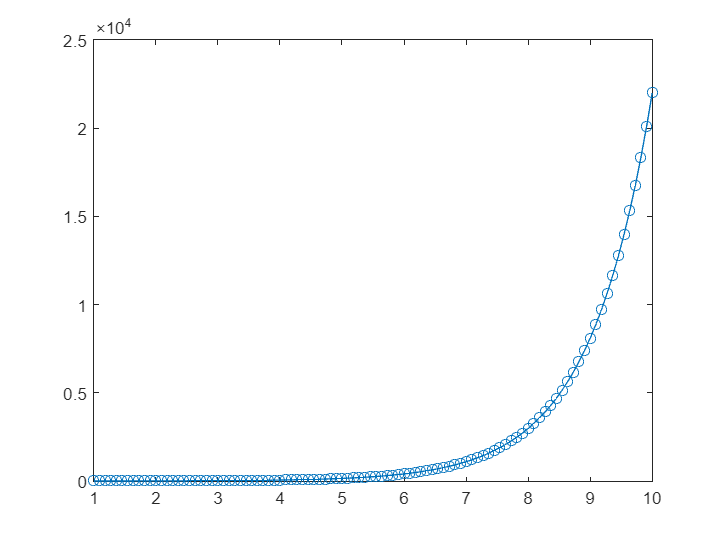

plot(n,b,'o-')

# 2.4. Estructuras de control

## Bucle for

La estructura` for` recorre un conjunto de elementos y en cada elemento ejecuta unas instrucciones. Permite repetir una orden un cierto número de veces.  La estructura en código de `for` es

                        `for` `variable=expresión`

                `Instrucciones`

             `end`

**Ejemplo. **Vamos a crear un vector de 10 compontes donde el valor de cada componente sea la posición que ocupa en el vector añadiendo 5 unidades:

for k=1:10
    v(k)=k+5;
end

**Ejemplo.** Definamos un vector $w$ cuyas componentes sean el doble que las de $v=(2,1,-3,9)$:

v=[2,1,-3,9]; w=[];
for k=1:length(v)
    w(k)=2*v(k);
end
w

w =        4              2             -6             18       


**Ejercicio 4.** Define un vector $v$ cuyas componentes sean la diferencia entre los elementos de $u=(1,2,5,-1,3,7,2)$.

u=[1,2,5,-1,3,7,2]; v=[];
for k=1:(length(u)-1)
    v(k)=u(k)-u(k+1);
end
v

v =       -1             -3              6             -4             -4              5       


## Condicional if

Esta estructura ejecuta unas instrucciones u otras dependiendo si se cumple una condición. La estructura en código de `if` es:

                        `if` `condición`

                `Instrucciones`

             `end`

o bien:

                        `if` `condición`

                `Instrucciones_SI`

                         `else`

                                `Instrucciones_NO`

             `end`

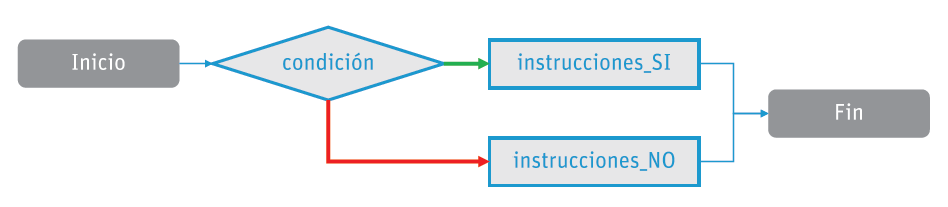

**Ejemplo.** Calcula los 100 primeros valores de la sucesión $x_{n}=\frac{n}{2}+\frac{1}{n}$. Modifica el programa para que se detenga cuando se cumpla $|x_{n}-\sqrt{2}|<10^{-5}$.

for n=1:1:100
    x(n)=n/2+1/n;
    if abs(x(n)-sqrt(2))<10^(-5)
        pause
    end
end
disp(x)

$$\left(\begin{array}{cccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccccc} \frac{3}{2} & \frac{3}{2} & \frac{11}{6} & \frac{9}{4} & \frac{27}{10} & \frac{19}{6} & \frac{51}{14} & \frac{33}{8} & \frac{83}{18} & \frac{51}{10} & \frac{123}{22} & \frac{73}{12} & \frac{171}{26} & \frac{99}{14} & \frac{227}{30} & \frac{129}{16} & \frac{291}{34} & \frac{163}{18} & \frac{363}{38} & \frac{201}{20} & \frac{443}{42} & \frac{243}{22} & \frac{531}{46} & \frac{289}{24} & \frac{627}{50} & \frac{339}{26} & \frac{731}{54} & \frac{393}{28} & \frac{843}{58} & \frac{451}{30} & \frac{963}{62} & \frac{513}{32} & \frac{1091}{66} & \frac{579}{34} & \frac{1227}{70} & \frac{649}{36} & \frac{1371}{74} & \frac{723}{38} & \frac{1523}{78} & \frac{801}{40} & \frac{1683}{82} & \frac{883}{42} & \frac{1851}{86} & \frac{969}{44} & \frac{2027}{90} & \frac{1059}{46} & \frac{2211}{94} & \frac{1153}{48} & \frac{2403}{98} & \frac{1251}{50} & \frac{2603}{102} & \frac{1353}{52} & \frac{2811}{106} & \frac{1459}{54} & \frac{3027}{110} & \frac{1569}{56} & \frac{3251}{114} & \frac{1683}{58} & \frac{3483}{118} & \frac{1801}{60} & \frac{3723}{122} & \frac{1923}{62} & \frac{3971}{126} & \frac{2049}{64} & \frac{4227}{130} & \frac{2179}{66} & \frac{4491}{134} & \frac{2313}{68} & \frac{4763}{138} & \frac{2451}{70} & \frac{5043}{142} & \frac{2593}{72} & \frac{5331}{146} & \frac{2739}{74} & \frac{5627}{150} & \frac{2889}{76} & \frac{5931}{154} & \frac{3043}{78} & \frac{6243}{158} & \frac{3201}{80} & \frac{6563}{162} & \frac{3363}{82} & \frac{6891}{166} & \frac{3529}{84} & \frac{7227}{170} & \frac{3699}{86} & \frac{7571}{174} & \frac{3873}{88} & \frac{7923}{178} & \frac{4051}{90} & \frac{8283}{182} & \frac{4233}{92} & \frac{8651}{186} & \frac{4419}{94} & \frac{9027}{190} & \frac{4609}{96} & \frac{9411}{194} & \frac{4803}{98} & \frac{9803}{198} & \frac{5001}{100} \end{array}\right)$$

**Ejercicio 5. **Escribe el código para reemplazar en el vector $v=(2, 2, 0, -2, 3, -7, 5, -1,2)$ los números positivos por 1 y los números negativos por un 0.

v=[2,2,0,-2,3,-7,5,-1,2]; w=[];
for k=1: length(v)
    if v(k)>0
        w(k)=1
    
    else v(k)<0
        w(k)=0
    end
end

w =        1       


w =        1              1       


ans = logical
   0


w =        1              1              0       


ans = logical
   1


w =        1              1              0              0       


w =        1              1              0              0              1       


ans = logical
   1


w =        1              1              0              0              1              0       


w =        1              1              0              0              1              0              1       


ans = logical
   1


w =        1              1              0              0              1              0              1              0       


w =        1              1              0              0              1              0              1              0              1       


w

w =        1              1              0              0              1              0              1              0              1       


# 2.5. Sucesión de Fibonacci en Matlab

La sucesión de Fibonacci es una sucesión infinita de números naturales donde cada nuevo término se obtiene como la suma de los dos anteriores:


$$x_{n+2}=x_{n+1}+x_{n}$$


Algunos de los primeros términos serían los siguientes:

1, 1, 2, 3, 5, 8, 13, ....

**Ejercicio 6.** Calcula los 50 primeros números de la sucesión de Fibonacci utilizando un bucle `for` y considerando $x_1=1$ y $x_2=1$. Deberás seguir los siguientes pasos:

- Crea un vector $x$ de ceros con 50 componentes.

- Almacena en las dos primeras componentes los dos primeros términos de la sucesión.

- Define los demás términos de la sucesión dentro de un bucle `for` que recorra cada componente del vector $x$.

x=[zeros(1,50)];
 x(1)=1

x =        1              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


 x(2)=1

x =        1              1              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


for k=3: length(x)
    x(k)=x(k-1)+x(k-2)
end

x =        1              1              2              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              0              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              0              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              0              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              0              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              0              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              0              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              0              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              0              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              0              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              0              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              0              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              0              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              0              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              0       


x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *       


x

x =        1              1              2              3              5              8             13             21             34             55             89            144            233            377            610            987           1597           2584           4181           6765          10946          17711          28657          46368          75025         121393         196418         317811         514229         832040              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *              *       
